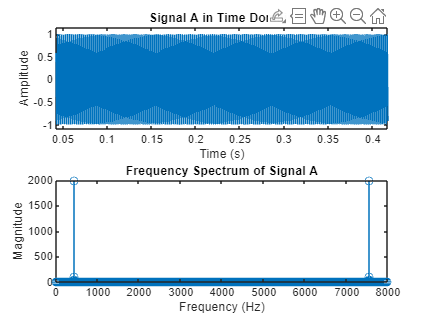

% Task 1: Observe the frequency spectrum of signal A
t = 0:1/8000:0.5;
A = sin(2*pi*440*t);

% Plot the time-domain signal
subplot(2, 1, 1);
plot(t, A);
ylim([-1.5 1.5])
title('Signal A in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Compute and plot the frequency spectrum
A_fft = fft(A);
frequencies = linspace(0, 8000, length(A_fft));
subplot(2, 1, 2);
stem(frequencies, abs(A_fft));
title('Frequency Spectrum of Signal A');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


% Load chirp.mat and observe its frequency spectrum
load('chirp.mat');
dt = t(2) - t(1); % Define the sampling interval
t_chirp = 0:dt:(length(y)-1)*dt;
chirp_fft = fft(y);
frequencies_chirp = linspace(0, 1/dt, length(chirp_fft));
figure; % Open a new figure window
subplot(2, 1, 1);
stem(t_chirp, y);
title('Chirp Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(2, 1, 2);
stem(frequencies_chirp, abs(chirp_fft));
title('Frequency Spectrum of Chirp Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');